# [Solution] Tensor contractions

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

Before showing the solution to the exercise, we will explain new function and important concepts.

## New function: `contract`

The updated code repository includes a new function `contract` (under `Tensor` directory) which encapsulates the processes we had for tensor contractions (`permute`, `reshape`, and matrix multiplication). First **read the description of the function**. You can do it (i) by opening `Tensor/contract.m` and reading the block of comments (green-colored), or (ii) by typing in the command window:

help contract

  < Description >
 
  C = contract(A,rankA,idA,B,rankB,idB [,idC] [,'-v']) 
 
  Contract tensors A and B. The legs to be contracted are given by idA
  and idB.
 
  < Input >
  A, B : [numeric array] Tensors.
  rankA, rankB : [integer] Rank of tensors. Since MATLAB removes the last
        trailing singleton dimensions, it is necessary to set rankA and
        rankB not to miss the legs of size 1 (or bond dimension 1,
        equivalently).
  idA, idB : [integer vector] Indices for the legs of A and B to be
         contracted. The idA(n)-th leg of A and the idB(n)-th leg of B will
         be contracted, for all 1 <= n <= numel(idA). idA and idB should
         have the same number of elements. If they are both empty, C will
         be given by the direct product of A and B.
  
  < Option >
  idC : [integer array] To permute the resulting tensor after contraction,
        assign the permutation indices as idC. If the dummy legs are
        attached (see the description of C below), th

If you see an error message that MATLAB cannot find file or directory, please re-run `startup.m`. The shortcut on the upper-right corner is very convenient in this regard!

We will give an example of using this new function. Consider rank-3 tensors `A` and `B`.

% it is always a good practice to start from the empty workspace!
clear

A = rand(4,5,3);
B = rand(6,4,5);

Contract the first and second legs of `A` to the second and third legs of `B`, respectively.

C = contract(A,3,[1 2],B,3,[2 3])

C =     4.8519    3.8797    3.6829    4.0338    4.4490    4.4406
    3.7536    3.3242    3.0114    4.0643    5.1058    3.4285
    4.2047    2.9206    2.9472    4.1654    4.2670    3.7584


The contract function also provides the permutation after the contraction.

C = contract(A,3,[1 2],B,3,[2 3],[2 1])

C =     4.8519    3.7536    4.2047
    3.8797    3.3242    2.9206
    3.6829    3.0114    2.9472
    4.0338    4.0643    4.1654
    4.4490    5.1058    4.2670
    4.4406    3.4285    3.7584


Note that the result here is the transpose of the above.

To see how the legs of `C` correspond to the legs of `A` and `B`, set `'-v'` option ("v" for "verbose"). Then also the real/CPU time and the memory occupation are measured.

C = contract(A,3,[1 2],B,3,[2 3],'-v');

Result leg (size): C1=A3 (3), C2=B1 (6)
Elapsed time: 0.0002918s, CPU time: 0s, Avg # of cores: 0


C = contract(A,3,[1 2],B,3,[2 3],[2 1],'-v');

Result leg (size): C1=B1 (6), C2=A3 (3)
Elapsed time: 0.000297s, CPU time: 0s, Avg # of cores: 0


If one makes any mistake, the routine gives relevant error message.

% The ranks are specified wrongly:
contract(A,2,[1 2],B,2,[2 3]); 
% The number of legs to be contracted do not match:
contract(A,3,[1 2],B,3,1);
% The sizes of the legs to be contracted do not match:
contract(A,3,[1 2],B,3,[1 2]);

Be aware of that **MATLAB automatically removes the last trailing singleton dimensions**. Here singletone dimension means the dimension whose size is one. For example, we can define a rank-5 tensor `F` whose last three legs have size 1 (or bond dimension 1, requivalently).

F = rand(3,4,1,1,1); % define F as rank-5

But when we query the size of `F`, it shows as rank-2.

size(F)

ans =      3     4


ismatrix(F)

ans = logical
   1


On the other hand, the singleton dimensions in the middle are not truncated:

F = rand(3,1,4);
size(F)

ans =      3     1     4


ismatrix(F)

ans = logical
   0


MATLAB does this automatic truncation to have better computational performance, but it can be a problem when such legs of size 1 need to be considered explicitly. That's why the function `contract` receive the inputs `rankA` and `rankB` (the ranks of tensors `A` and `B`) independently from the inputs `A` and `B`. Then the last trailing singleton dimensions of multi-dimensional arrays can be treated properly.

**Try to look inside the code of **`contract`**, focusing on the main computational part.** You can identify the part by searching for the phrase "`computational` `part`". Experienced MATLAB users are also advised to see how the **sanity check of input** is done.

## Brief remark: Vectors as "rank-2" tensors

In the lecture video, I explained why rank-1 tensors actually do not appear in numerical calculations. Let me repeat the explanation here.

For example, a column vector $C^{\gamma }$ can be depicted as a rank-1 tensor with a single incoming leg.

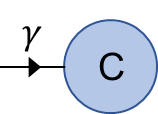

Similarly, one can also depict a row vector as a rank-1 tensor with a single outgoing leng. Then, the multiplication of a row vector A, a matrix B, and a column vector C, i.e., $A_{\beta} B^{\beta}_{\>\>\>\gamma} C^{\gamma}$, can be represented as the following contraction:

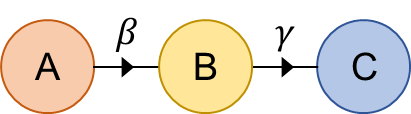

However, as I explained in the video, **the vectors are represented as rank-2 tensors in most of numerical implementations, by attaching dummy legs of size 1**. Then the above examples of $C^{\gamma }$ and $A_{\beta} B^{\beta}_{\>\>\>\gamma} C^{\gamma}$ will be re-drawn as:

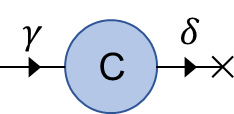

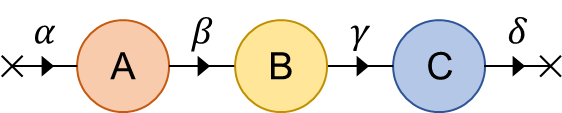

Here A and C have two legs. "x" marks at the end of newly attached legs denote that the legs are dummy legs with singleton dimension. There are two reasons:

**1. Rank-1 tensor cannot describe non-trivial symmetry sectors.** This is physical reason. The tensor networks with symmetries will be covered later in the lecture course; here we will give only a brief explanation. When the system has symmetries (e.g., charge and spin conservation), we can express the tensors in block-diagonal form. Each block is called symmetry sector, and each leg of symmetry sector carries quantum numbers. The quantum numbers should satisfy "Kirchhoff's law". With this law, the unique leg of rank-1 tensor can carry only trivial quantum numbers that amount to zeros.

**2. MATLAB treats row/column vectors as "thin" matrices.** This is technical but immediate reason. Try the following:

A = (1:3) % row vector

A =      1     2     3


size(A)

ans =      1     3


ismatrix(A)

ans = logical
   1


B = (4:6).' % column vector

B =      4
     5
     6


size(B)

ans =      3     1


ismatrix(B)

ans = logical
   1


For row (column) vectors, the first (second) dimensions are singleton, which correspond to dummy legs. In the above diagrams, the dummy leg of A (C) is incoming (outgoing) so that the tensor has a pair of incoming and outgoing legs, consistent with the case of the matrix B.

## Solution to Exercise (a): First contract A and C, and then contract AC and B

Now we are ready to show the solution to exercise. First, let's prepare the tensors again. Here we choose larger leg dimensions to make the better comparison.

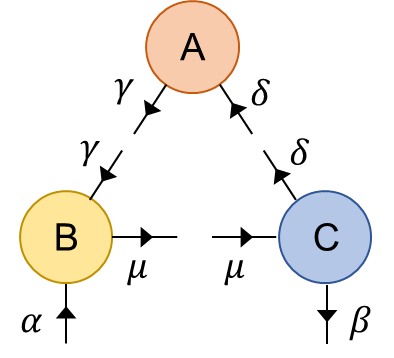

clear

% leg dimensions
d_a = 101; % d_alpha
d_b = 102; % d_beta
d_c = 103; % d_gamma
d_d = 104; % d_delta
d_m = 105; % d_mu

A = rand(d_c,d_d);     % tensor A(gamma,delta)
B = rand(d_a,d_m,d_c); % tensor B(alpha,mu,gamma)
C = rand(d_b,d_m,d_d); % tensor C(beta,mu,delta)

**Way 1: contract B and C first, then contract with A (as done in the demonstration)**

tobj = tic2;
BC = contract(B,3,2,C,3,2,'-v'); % BC(alpha,gamma,beta,delta)

Result leg (size): C1=A1 (101), C2=A3 (103), C3=B1 (102), C4=B3 (104)
Elapsed time: 0.1551s, CPU time: 1.3s, Avg # of cores: 8.382


ABC1 = contract(BC,4,[2 4],A,2,[1 2],'-v'); % ABC(alpha,beta)

Result leg (size): C1=A1 (101), C2=A3 (102)
Elapsed time: 0.1791s, CPU time: 1.44s, Avg # of cores: 8.041


toc2(tobj,'-v'); % total real/CPU time

Elapsed time: 0.403s, CPU time: 2.83s, Avg # of cores: 7.022


**Way 2: contract A and C first, then contract with B (as asked in the Exercise)**

Note that we should use the same tensors `A`, `B`, and `C` for fair comparison!

% % Way 2: contract A and C first
tobj = tic2;
AC = contract(A,2,2,C,3,3,'-v'); % AC(gamma,beta,mu)

Result leg (size): C1=A1 (103), C2=B1 (102), C3=B2 (105)
Elapsed time: 0.004531s, CPU time: 0.03s, Avg # of cores: 6.622


ABC2 = contract(B,3,[2 3],AC,3,[3 1],'-v'); % ABC(alpha,beta)

Result leg (size): C1=A1 (101), C2=B2 (102)
Elapsed time: 0.003436s, CPU time: 0.04s, Avg # of cores: 11.64


toc2(tobj,'-v'); % total real/CPU time

Elapsed time: 0.01445s, CPU time: 0.07s, Avg # of cores: 4.845


We should always check whether two different ways give the same result.

sum(abs(ABC1(:)-ABC2(:))) % absolute error

ans = 3.2105e-06

mean(abs((ABC1(:)-ABC2(:))./ABC1(:))) % relative error

ans = 2.2066e-15

The relative error is of the order of double precision $\sim$1e-16.

The time complexity is reflected in the CPU time lapse. We see that the way 1 took about 40 times longer CPU time than the way 2.

The computational cost for the way 1 is $O (d_\alpha d_\beta d_\gamma d_\delta d_\mu) + O(d_\alpha d_\beta d_\gamma d_\delta)$ and for the way 2 is $O(d_\beta d_\gamma d_\delta d_\mu) + O(d_\alpha d_\beta d_\gamma d_\mu)$. In this example we chose $d$'s to be all similar, so the way 1's cost is about $d$ (~100) times large than the way 2's, which is consistent with our numerical experiment. (Note again, that actual ratio of CPU times may depend on many factors.)